# The mass of a finite particle

This script will show that a finite particle oposes to be acelerated i.e., it has a mass.

The first finite size particle model is very simple:

- Two point elements with charge Q/2 on the horizontal axis separated by a distance of 2*r_o 

- The two elements are bounded by a nuclear force

- The particle is acelerated with constant acceleration


% Solving for the arrival time of a particle at constant aceleration
% a   : Aceleration
% r_o : Particle radious
% c   : Speed of light
% K   : eletrostatic constant
% t   : time to reach a target
% Q   : Particle charge
syms a Q r_o c K t real;
assumeAlso(a > 0)
assumeAlso(r_o > 0)
assumeAlso(c > 0)
assumeAlso(K > 0)
assumeAlso(t > 0)
assumeAlso(Q > 0)


## Solving for the arrival time

I'll solve for the forces that the particle experiment at time equal zero. 

eq1 = -a/2*t^2-c*t+2*r_o==0 % right corpuscle moving towards the left element

$$eq1 = 2\,r_{o}-c\,t-\frac{a\,t^{2}}{2}=0$$

t_1=solve(eq1,t) % The time it takes to reach the left element 

$$t\_1 = -\frac{c-\sqrt{c^{2}+4\,a\,r_{o}}}{a}$$

t_1 = t_1(1)

$$t\_1 = -\frac{c-\sqrt{c^{2}+4\,a\,r_{o}}}{a}$$

eq2 = -a/2*t^2+c*t-2*r_o==0 % The equation of the corpuscle traveling from left to right element

$$eq2 = -2\,r_{o}+c\,t-\frac{a\,t^{2}}{2}=0$$

t_2= solve(eq2,t) % The time it takes to reach the right element

$$t\_2 = \left(\begin{array}{c} \frac{c+\sqrt{c^{2}-4\,a\,r_{o}}}{a}\\ \frac{c-\sqrt{c^{2}-4\,a\,r_{o}}}{a} \end{array}\right)$$

t_2=t_2(2) % I only take the shortest time

$$t\_2 = \frac{c-\sqrt{c^{2}-4\,a\,r_{o}}}{a}$$

vpa(subs(t_1,[a,r_o,c],[1,1.0e-15,1]))-vpa(subs(t_2,[a,r_o,c],[1,1.0e-15,1]))

$$ans = -0.0000000000000000000000000000040000000001946799263974006163732$$

D_a=simplify(1/(t_2^2)-1/(t_1^2)) % The force is due to differences in arrival time

$$D\_a = \frac{a^{2}}{{\left(c-\sqrt{c^{2}-4\,a\,r_{o}}\right)}^{2}}-\frac{a^{2}}{{\left(c-\sqrt{c^{2}+4\,a\,r_{o}}\right)}^{2}}$$

D_a= taylor(D_a,a,Order=4) % Lets take an aproximation

$$D\_a = -\frac{a}{r_{o}}-\frac{a^{3}\,r_{o}}{c^{4}}$$

F=K*Q^2/(4*c^2)*D_a % The reaction force experimented by the acelerated particle 

$$F = -\frac{K\,Q^{2}\,\left(\frac{a}{r_{o}}+\frac{a^{3}\,r_{o}}{c^{4}}\right)}{4\,c^{2}}$$

Hence if you acelerate a electically charged finite-sized particle, it will opose the aceleration. In other words particles have intertia and is origen is the fact that electric charges have dimensions. 

## Energy and Mass

U= -K*Q^2/4*int(1/t^2,t,Inf,2*r_o) % The energy required to bound the two elements of the particle

$$U = \frac{K\,Q^{2}}{8\,r_{o}}$$

syms U
F_net=expand(simplify(subs(F,Q^2,8*U*r_o/K))) % The reaction force in units of the energy

$$F\_net = -\frac{2\,U\,a}{c^{2}}-\frac{2\,U\,a^{3}\,{r_{o}}^{2}}{c^{6}}$$

where $r_o$ is very small and c is very large. 

The first term of the total reactive force is:

F_net = taylor(F_net,Order=2) % The first term

$$F\_net = -\frac{2\,U\,a}{c^{2}}$$

The sum of all the forces is equal zero, and $F_{net}+ma=0$, then $m=\frac{2U}{c^2}$ or the $U \approx mc^2$  the famus Einstein equation. 

## The expanded model of the particle

Let use a more complex model of the particle this time lets use 6 elements to model the finite-sized paticle. Each element is in the corner of a regular octahedron:

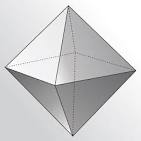.

The particle resides in the origen, and each one of the six elements is at a distance $r_o$ form the origen. The constant aceleration is in the positve $x$ direction. The analysis involve estimating the time of arrival of each corpuscle to the other elements.

eq3 = (c*t)^2 - r_o^2 - (r_o-1/2*a*t^2)^2 == 0 % corpuscle moving from off x-axis left

$$eq3 = c^{2}\,t^{2}-{r_{o}}^{2}-{\left(r_{o}-\frac{a\,t^{2}}{2}\right)}^{2}=0$$

t_dL= solve(eq3,t) % The time it takes for corpuscles to reach diagonal left element 

$$t\_dL = \left(\begin{array}{c} \sqrt{\frac{2\,\left(a\,r_{o}+\sqrt{c^{4}+2\,a\,c^{2}\,r_{o}-a^{2}\,{r_{o}}^{2}}+c^{2}\right)}{a^{2}}}\\ \sqrt{\frac{2\,\left(a\,r_{o}-\sqrt{c^{4}+2\,a\,c^{2}\,r_{o}-a^{2}\,{r_{o}}^{2}}+c^{2}\right)}{a^{2}}} \end{array}\right)$$

t_dL = t_dL(2)

$$t\_dL = \sqrt{\frac{2\,\left(a\,r_{o}-\sqrt{c^{4}+2\,a\,c^{2}\,r_{o}-a^{2}\,{r_{o}}^{2}}+c^{2}\right)}{a^{2}}}$$

eq4 = (c*t)^2 - r_o^2 - (r_o + 1/2*a*t^2)^2 == 0 % diagnoal corpuscle to right element

$$eq4 = c^{2}\,t^{2}-{r_{o}}^{2}-{\left(r_{o}+\frac{a\,t^{2}}{2}\right)}^{2}=0$$

t_dR= solve(eq4,t) % Diagonal Time to reach the right element

$$t\_dR = \left(\begin{array}{c} \sqrt{\frac{2\,\left(\sqrt{c^{4}-2\,a\,c^{2}\,r_{o}-a^{2}\,{r_{o}}^{2}}-a\,r_{o}+c^{2}\right)}{a^{2}}}\\ \sqrt{-\frac{2\,\left(a\,r_{o}+\sqrt{c^{4}-2\,a\,c^{2}\,r_{o}-a^{2}\,{r_{o}}^{2}}-c^{2}\right)}{a^{2}}} \end{array}\right)$$

t_dR = t_dR(2) % The shortest time

$$t\_dR = \sqrt{-\frac{2\,\left(a\,r_{o}+\sqrt{c^{4}-2\,a\,c^{2}\,r_{o}-a^{2}\,{r_{o}}^{2}}-c^{2}\right)}{a^{2}}}$$


eq5= (1/2*a*t^2)^2-(c*t)^2 + (2*r_o)^2==0 % The equation from off x-axis to the opposite element

$$eq5 = 4\,{r_{o}}^{2}-c^{2}\,t^{2}+\frac{a^{2}\,t^{4}}{4}=0$$

t_5= solve(eq5,t)

$$t\_5 = \left(\begin{array}{c} \sqrt{\frac{2\,\left(c^{2}+\sqrt{-\left(c^{2}+2\,a\,r_{o}\right)\,\left(-c^{2}+2\,a\,r_{o}\right)}\right)}{a^{2}}}\\ \sqrt{\frac{2\,\left(c^{2}-\sqrt{-\left(c^{2}+2\,a\,r_{o}\right)\,\left(-c^{2}+2\,a\,r_{o}\right)}\right)}{a^{2}}} \end{array}\right)$$

t_5=t_5(2) % The shortest time

$$t\_5 = \sqrt{\frac{2\,\left(c^{2}-\sqrt{-\left(c^{2}+2\,a\,r_{o}\right)\,\left(-c^{2}+2\,a\,r_{o}\right)}\right)}{a^{2}}}$$

eq6= (1/2*a*t^2)^2-(c*t)^2 + 2*r_o^2 == 0 % Off axis to the next off axis

$$eq6 = 2\,{r_{o}}^{2}-c^{2}\,t^{2}+\frac{a^{2}\,t^{4}}{4}=0$$

t_6= solve(eq6,t)

$$t\_6 = \left(\begin{array}{c} \sqrt{\frac{2\,\left(\sqrt{c^{4}-2\,a^{2}\,{r_{o}}^{2}}+c^{2}\right)}{a^{2}}}\\ \sqrt{-\frac{2\,\left(\sqrt{c^{4}-2\,a^{2}\,{r_{o}}^{2}}-c^{2}\right)}{a^{2}}} \end{array}\right)$$

t_6=t_6(2) % The shortest time

$$t\_6 = \sqrt{-\frac{2\,\left(\sqrt{c^{4}-2\,a^{2}\,{r_{o}}^{2}}-c^{2}\right)}{a^{2}}}$$

Now, I'll compute the reactive forces for each one of the element to element interactions

syms d v real positive
cos_L = cos(pi/4);
cos_R = cos(pi/4);
cos_5 = (1/2*a*t_5^2)/sqrt((2*r_o)^2+(1/2*a*t_5^2)^2);
cos_6 = (1/2*a*t_6^2)/sqrt(2*r_o^2+(1/2*a*t_6^2)^2);

F_1 = -1/(c*t_1)^2 - 4/(c*t_dL)^2*cos_L; % Left element
F_2 = +1/(c*t_2)^2 + 4/(c*t_dR)^2*cos_R; % Right element
F_3 = 1/(c*t_5)^2*cos_5; % The two off axis elements

F_3 = F_3 + 2/(c*t_6)^2*cos_6; % The  two sides of the off-axis elements
F_3 = F_3 - 1/(c*t_dL)^2*cos_L; % add the right element to the off-axis
F_3 = F_3 + 1/(c*t_dR)^2*cos_R; % add the left element to off-axis

F_netp = simplify(F_1 + F_2 + 4*F_3,steps=100); % One left, one right plus the four off-axis
F_net = K*(Q/6)^2*simplify(taylor(F_netp,a,Order=2))

$$F\_net = -\frac{\sqrt{2}\,K\,Q^{2}\,a}{18\,c^{2}\,r_{o}}$$

% The Binding energy of the regular octahedron
U_1 = K*(Q/6)^2/(2*r_o) % Right to left

$$U\_1 = \frac{K\,Q^{2}}{72\,r_{o}}$$

U_2 = K*(Q/6)^2/(sqrt(2)*r_o) % off diagonal 

$$U\_2 = \frac{\sqrt{2}\,K\,Q^{2}}{72\,r_{o}}$$

U_net = simplify(3*U_1 + 12*U_2)

$$U\_net = \frac{K\,Q^{2}\,\left(4\,\sqrt{2}+1\right)}{24\,r_{o}}$$

syms U_net Q2
qeU = U_net - (K*Q2*(4*sqrt(sym(2)) + 1))/(24*r_o) == 0

$$qeU = U_{\mathrm{net}}-\frac{K\,Q_{2}\,\left(4\,\sqrt{2}+1\right)}{24\,r_{o}}=0$$

simplify(solve (qeU,Q2))

$$ans = \frac{24\,U_{\mathrm{net}}\,r_{o}}{K\,\left(4\,\sqrt{2}+1\right)}$$

F_net

$$F\_net = -\frac{\sqrt{2}\,K\,Q^{2}\,a}{18\,c^{2}\,r_{o}}$$

F_u=simplify(subs(F_net,Q^2,(24*U_net*r_o)/(K*(4*sqrt(sym(2)) + 1))))

$$F\_u = \frac{U_{\mathrm{net}}\,a\,\left(\frac{4\,\sqrt{2}}{93}-\frac{32}{93}\right)}{c^{2}}$$

vpa(subs(F_u,[a,c,r_o],[a,1,1]))

$$ans = -0.28325963172588838499777682906625\,U_{\mathrm{net}}\,a$$

The inertial mass of the regular octahedron is lower that that of the two element particle.

## Add the central element to the regular octahedron

eq1p = -a/2*t^2-c*t+r_o==0 % right corpuscle moving towards the left element

$$eq1p = r_{o}-c\,t-\frac{a\,t^{2}}{2}=0$$

t_1p=solve(eq1p,t) % The time it takes to reach the left element 

$$t\_1p = -\frac{c-\sqrt{c^{2}+2\,a\,r_{o}}}{a}$$

t_1p = t_1p(1)

$$t\_1p = -\frac{c-\sqrt{c^{2}+2\,a\,r_{o}}}{a}$$

eq2p = -a/2*t^2+c*t-r_o==0 % The equation of the corpuscle traveling from left to right element

$$eq2p = -r_{o}+c\,t-\frac{a\,t^{2}}{2}=0$$

t_2p= solve(eq2p,t) % The time it takes to reach the right element

$$t\_2p = \left(\begin{array}{c} \frac{c+\sqrt{c^{2}-2\,a\,r_{o}}}{a}\\ \frac{c-\sqrt{c^{2}-2\,a\,r_{o}}}{a} \end{array}\right)$$

t_2p=t_2p(2) % I only take the shortest time

$$t\_2p = \frac{c-\sqrt{c^{2}-2\,a\,r_{o}}}{a}$$

eq_c = (1/2*a*t^2)^2-(c*t)^2 + r_o^2==0 % Points off axis

$$eq\_c = {r_{o}}^{2}-c^{2}\,t^{2}+\frac{a^{2}\,t^{4}}{4}=0$$

t_c= solve(eq_c,t)

$$t\_c = \left(\begin{array}{c} \sqrt{\frac{2\,\left(c^{2}+\sqrt{-\left(c^{2}+a\,r_{o}\right)\,\left(-c^{2}+a\,r_{o}\right)}\right)}{a^{2}}}\\ \sqrt{\frac{2\,\left(c^{2}-\sqrt{-\left(c^{2}+a\,r_{o}\right)\,\left(-c^{2}+a\,r_{o}\right)}\right)}{a^{2}}} \end{array}\right)$$

t_c=t_c(2) % The shortest time

$$t\_c = \sqrt{\frac{2\,\left(c^{2}-\sqrt{-\left(c^{2}+a\,r_{o}\right)\,\left(-c^{2}+a\,r_{o}\right)}\right)}{a^{2}}}$$

cosp = (1/2*a*t_c^2)/sqrt(r_o^2+(1/2*a*t_c^2)^2);

F_cp = -1/(c*t_1p)^2 + 1/(c*t_2p)^2 + 4/(c*t_c)^2*cosp;
F_1p = F_1 - 1/(c*t_1p)^2; % Left element
F_2p = F_2 + 1/(c*t_2p)^2; % Righ element
F_3p = F_3 + 1/(c*t_c)^2*cosp; %Off axis elements
F_netcp = simplify(F_cp + F_1p + F_2p + 4*F_3p,steps=100); % One left, one right plus the four off-axis
F_netc = K*(Q/7)^2*simplify(taylor(F_netcp,a,Order=2))

$$F\_netc = -\frac{2\,\sqrt{2}\,K\,Q^{2}\,a}{49\,c^{2}\,r_{o}}$$

% The Binding energy of the regular octahedron with a central element
U_p = K*(Q/7)^2/(r_o) % Elements pairs separed by r_o

$$U\_p = \frac{K\,Q^{2}}{49\,r_{o}}$$

U_1 = K*(Q/7)^2/(2*r_o) % Elements  pairs separed by the sqrt(2)r_o

$$U\_1 = \frac{K\,Q^{2}}{98\,r_{o}}$$

U_2 = K*(Q/7)^2/(sqrt(2)*r_o) % Elements pairs separated by 2r_o

$$U\_2 = \frac{\sqrt{2}\,K\,Q^{2}}{98\,r_{o}}$$

U_net = simplify(3*U_1 + 12*U_2 + 6*U_p) % The 21 pairs of element to element interactions.

$$U\_net = \frac{3\,K\,Q^{2}\,\left(4\,\sqrt{2}+5\right)}{98\,r_{o}}$$

syms U_net Q2
qeU = U_net - (3*K*Q2*(4*sqrt(sym(2)) + 5))/(98*r_o) == 0

$$qeU = U_{\mathrm{net}}-\frac{3\,K\,Q_{2}\,\left(4\,\sqrt{2}+5\right)}{98\,r_{o}}=0$$

simplify(solve (qeU,Q2))

$$ans = \frac{98\,U_{\mathrm{net}}\,r_{o}}{3\,K\,\left(4\,\sqrt{2}+5\right)}$$

F_netc

$$F\_netc = -\frac{2\,\sqrt{2}\,K\,Q^{2}\,a}{49\,c^{2}\,r_{o}}$$

F_uc=simplify(subs(F_netc,Q^2,(98*U_net*r_o)/(3*K*(4*sqrt(sym(2)) + 5))))

$$F\_uc = \frac{U_{\mathrm{net}}\,a\,\left(\frac{20\,\sqrt{2}}{21}-\frac{32}{21}\right)}{c^{2}}$$

vpa(subs(F_uc,[a,c,r_o],[a,1,1]))

$$ans = -0.17693946440657614399839169122886\,U_{\mathrm{net}}\,a$$

The inertial mass of the regular octahedron with a central element is even lower. 

The implications is that it may be possible to find a charge distribution that will explain the oserved mass of charged particles.